# Radio Communication System

## *Simulation Script*

Authors:

Leonard Berresheim - s0556126

Ali Jahanbakhsh       - s0565379

Mihail Milchev           - s0560818

clc, clear variables; % clear all variables
addpath('subfunctions'); % add directory "subfunctions" to path
format long;

## Global Simulation Parameters

**ebN0dB **defines the **S**ignal to **N**oise **R**atio *(short SNR)* per Bit in dB for the **A**dditive **W**hite **G**aussian **N**oise *(short AWGN)* that will be applied on the mapped signal later on. The system will be tested with varrious values for SNR

ebN0dB = 0:10; % SNR (per bit) in dB
nBits = 10e3; % simulate nBits bits per simulation loop

**Constellation **is the modulation format that will be use to map the incoming bitsequence.

As an example, for the modulation format **Q**uadrature **P**hase **S**hift **K**ey *(short QPSK) *the bitsequence is mapped arcording to *Table 1.*

% Table 1
Dezimalzahl = [0;1;2;3];
Bitwert = dec2bin(Dezimalzahl);
Index = [1;2;3;4];
Konstellationspunkt = [-1-i;-1+i;1-j;1+j];
table(Bitwert,Dezimalzahl,Index, Konstellationspunkt)

ans = 4×4 table
    Bitwert    Dezimalzahl    Index    Konstellationspunkt
    _______    ___________    _____    ___________________

      00            0           1             -1-1i       
      01            1           2             -1+1i       
      10            2           3              1-1i       
      11            3           4              1+1i       


*Notice:* *the index value is shifted by 1 due to the fact that matlab starts indexing at 1 instead of 0*

The function handler **berTheoAWGN**(SNR, M) returns the theoretical **B**it-**E**rror-**R**elation of the **AWGN**-channel for chosen modulation format. It expects the **S**ignal-to-**N**oise-**R**atio in **linear** units and the number **M** of constellation symbols in given format.

The function handler **berTheoFading**(SNR, M, K) returns the theoretical **ber** of the **Rayleigh **and** Rician **fading channel. It additionaly also has as input parameter the **K**-factor.

 *(The**** AWGN/Rayleigh ****and**** Rician**** channel will be explained in more detailed later on)*

**M **gives the number of constalltion symbols in the format. 

**berTheoAWGN** 

[constellation, berTheoAWGN, berTheoFading, M] = DK16PCUe_ModFormats('qpsk');

constellation =  -1.000000000000000 - 1.000000000000000i  1.000000000000000 - 1.000000000000000i -1.000000000000000 + 1.000000000000000i  1.000000000000000 + 1.000000000000000i


berTheoAWGN = function_handle with value:
    @(SNR,M)berawgn(10*log10((SNR/log2(M))),'qam',M)


berTheoFading = function_handle with value:
    @(SNR,M,K)berfading(10*log10((SNR/log2(M))),'qam',M,1,K)


M =      4


## Simulation 

### Generating the bitsequence

**generateBits()** generates a random bitsequence of length **nBits**.

bits = generateBits(nBits);

### **Mapping the bitsequence**

**mapper() **maps the bitsequence **bits** according to the modulation format **constellation** defined before.

mapped_signal = mapper(bits, constellation);

### Adding AWGN to the mapped signal

**add_awgn() **adds the noise to the mapped signal **mapped_signal **for each SNR value in **ebN0dB**.

mapped_signal_AWGN_noise = add_awgn(mapped_signal,ebN0dB,M);

### Demapping the signal

Due to the faultiness of the transmission canal signal at the output of the canal doesn't match the constellation points of the constellation format.

**decision() ** matches each constellation point of mapped_signal_AWGN_noise to the nearest constellation point in **constellation;**

decided_signal = decision(mapped_signal_AWGN_noise, constellation);

**demapper() **demappes the signal according to the constellation table.

As an example, for the modulation format **Q**uadrature **P**hase **S**hift **K**ey *(short QPSK) *the signal is demapped arcording to *Table 2.*

% Table 2
Dezimalzahl = [0;1;2;3];
Bitwert = dec2bin(Dezimalzahl);
Index = [1;2;3;4];
Konstellationspunkt = [-1-i;-1+i;1-j;1+j];
table(Konstellationspunkt,Index,Dezimalzahl, Bitwert)

ans = 4×4 table
    Konstellationspunkt    Index    Dezimalzahl    Bitwert
    ___________________    _____    ___________    _______

           -1-1i             1           0           00   
           -1+1i             2           1           01   
            1-1i             3           2           10   
            1+1i             4           3           11   


demapped_bits = demapper(decided_signal,constellation);

### Counting Errors

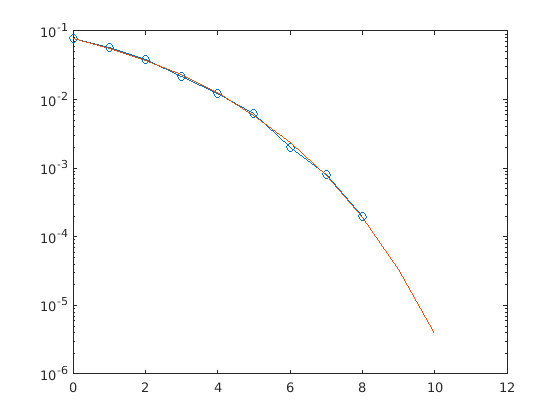

[nErr,ber] = countErrors(demapped_bits,bits);
% Numerische Berechnung
%P_AWGN = 0.5*erfc(sqrt(ebN0dB));
% ebN0dB needs to be converted from dB to linear units first and 
P_AWGN = berTheoAWGN(10.^(ebN0dB./10)*log2(M),M);

semilogy(ebN0dB, ber, "-o", ebN0dB, P_AWGN);

xlim([0 12])
ylim([10^(-6) 10^(-1)])



%fprintf("Anzahl der Fehler: " + nErr + "\n");
%fprintf("Fehlerverhältnis: " + ber*100 + "%%\n");

## Simulation as a loop

So far the simulation has been done with a fixed number of Bits. This doesnt necessarily give a informative Bit-Error-Relation. 

Hence the simulation will now be implemented as a loop with a specified number of Error and a specified number of Bits before the simulation terminates

### Defining simulation parameters

The simulation will terminate whenn **nMinErr **are reached or when **nMaxBits** are exceeded.

In the simulation loop **nBitsPerLoop** bits will be handled at once.

The simulation will return the **ber** *(Bit-Error-Ratio)* for each **SNR** *(Signal-to-Noise-Ratio)*

nMinErr = 100;
nBitsPerLoop = 10e3;
nMaxBits = 10*nBitsPerLoop;
ber = zeros(length(ebN0dB), 1);

### Simulation loop

for i=1:length(ebN0dB)
    nBits = nBitsPerLoop;
    nTotalErr = 0;
    while((nTotalErr <= nMinErr) && (nBits <= nMaxBits))
        bits = generateBits(nBitsPerLoop);
        mapped_signal = mapper(bits, constellation);
        mapped_signal_AWGN_noise = add_awgn(mapped_signal,ebN0dB(i),M);
        decided_signal = decision(mapped_signal_AWGN_noise, constellation);
        demapped_bits = demapper(decided_signal,constellation);
        [nErr,x_ber] = countErrors(demapped_bits,bits);
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%      
        nTotalErr = nTotalErr + nErr;
        nBits = nBits + nBitsPerLoop;
    end
    ber(i) = nTotalErr / nBits;    
end



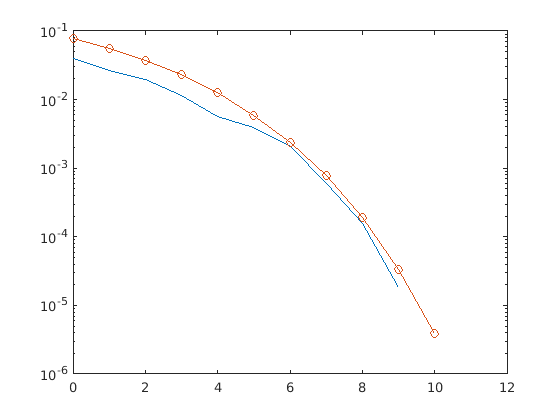

semilogy(ebN0dB, P_AWGN, ebN0dB, ber, "-o");

xlim([0 12])
ylim([10^(-6) 10^(-1)])

### Implement Rayleighkanal

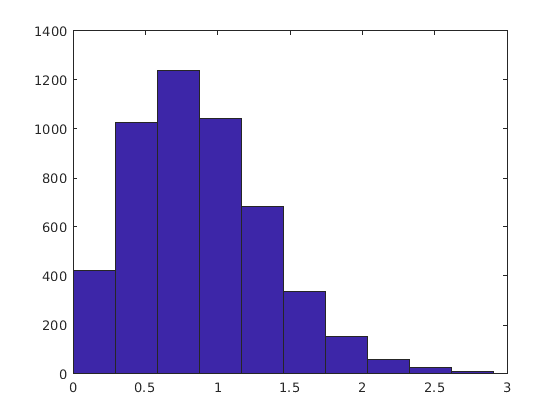

nSamp = length(mapped_signal);
canal_coefs = radioFadingChannel(nSamp);
hist(abs(canal_coefs));

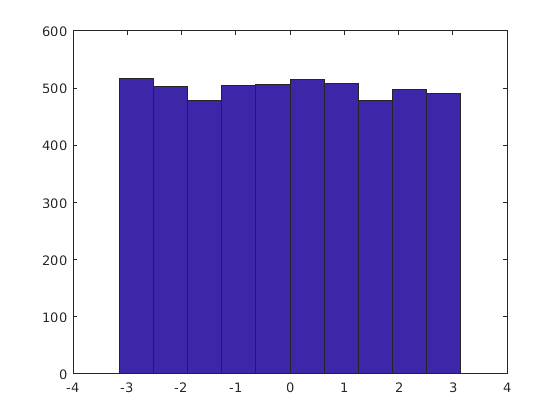

hist(angle(canal_coefs));


mapped_signal_fading = mapped_signal .* canal_coefs;

mapped_signal_fading_AWGN = add_awgn(mapped_signal_fading,ebN0dB,M);

mapped_signal_received =  mapped_signal_fading_AWGN ./ canal_coefs;

decided_signal = decision(mapped_signal_received, constellation);

demapped_bits = demapper(decided_signal,constellation);

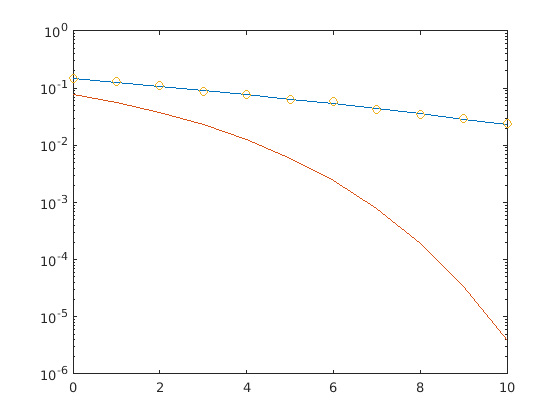

[nErr,ber] = countErrors(demapped_bits,bits);
% For rayleigh k = 0
P_Rayleigh = berTheoFading(10.^(ebN0dB./10)*log2(M),M,0);
P_AWGN = berTheoAWGN(10.^(ebN0dB./10)*log2(M),M);

semilogy(ebN0dB, P_Rayleigh, ebN0dB, P_AWGN, ebN0dB, ber, "o");